Automatically reads a colour pattern image from hard disc, and returns an array representing the colour pattern.

image = image(:,:,1) =

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9882    1.0000    1.0000    1.0000    0.9686    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9216    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9686    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.8471    1.0000    1.0000    1.0000    1.0000    1.0000    0.9647    1.0000    0.9216    1.0000    1.0000    0.9686    1.0000    1.0000    1.

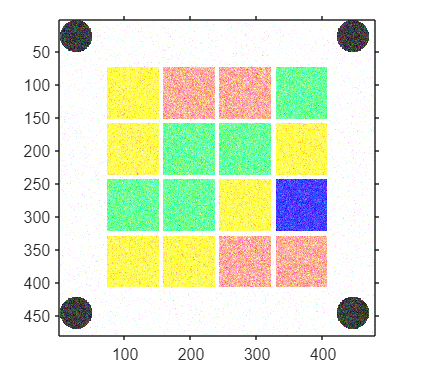

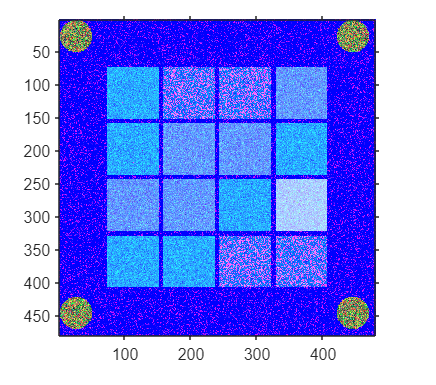

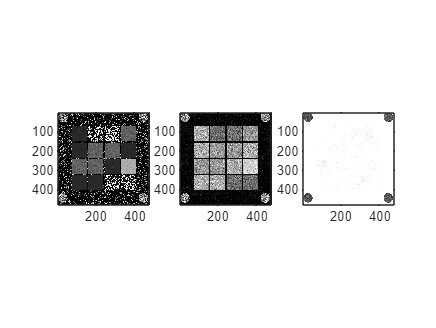

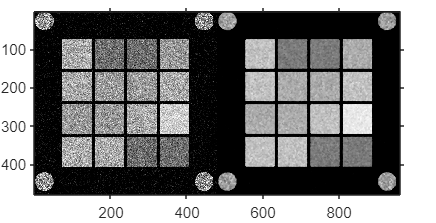

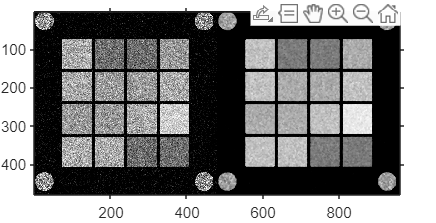

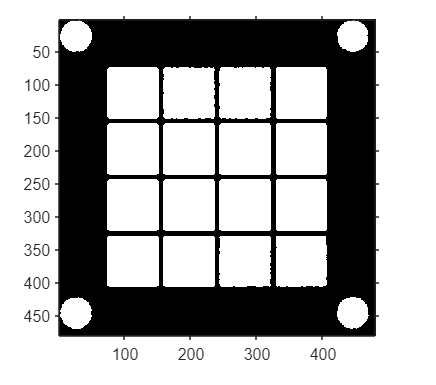

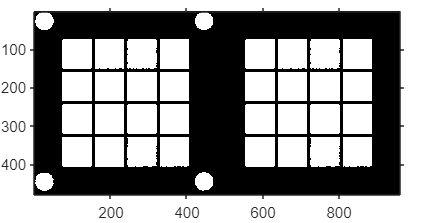

  112.5000  112.5000
  112.5000  197.5000
  112.5000  282.5000
  112.5000  367.5000
  197.3106  112.6149
  197.5000  197.5000
  197.5000  282.5000
  197.5000  367.5000
  282.4539  112.3941
  282.5000  197.5000
  282.5000  282.5000
  282.4464  367.5285
  367.5000  112.5000
  367.5000  197.5000
  367.5000  282.5000
  367.4711  367.5854

  112.5000  112.5000
  112.5000  197.5000
  112.5000  282.5000
  112.5000  367.5000
  197.3106  112.6149
  197.5000  197.5000
  197.5000  282.5000
  197.5000  367.5000
  282.4539  112.3941
  282.5000  197.5000
  282.5000  282.5000
  282.4464  367.5285
  367.5000  112.5000
  367.5000  197.5000
  367.5000  282.5000
  367.4711  367.5854



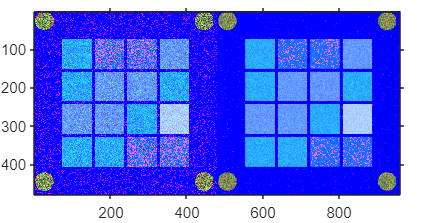

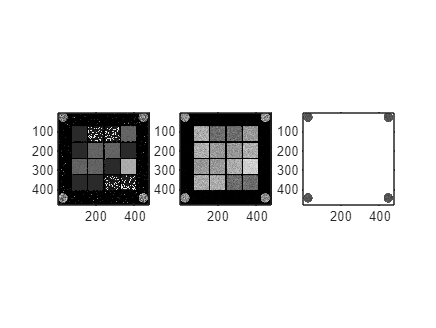

yellow
    0.1667    0.6902    1.0000

red
    0.1226    0.3529    1.0000

red
    0.1078    0.4019    1.0000

green
    0.4060    0.6392    1.0000

yellow
    0.1667    0.5176    1.0000

green
    0.4256    0.5732    1.0000

green
    0.3662    0.5738    1.0000

yellow
    0.1667    0.6471    1.0000

green
    0.3465    0.5294    1.0000

green
    0.3990    0.6039    1.0000

yellow
    0.1667    0.7098    1.0000

blue
    0.6536    0.8549    1.0000

yellow
    0.1667    0.7373    1.0000

yellow
    0.1667    0.6824    1.0000

red
    0.0775    0.4431    1.0000

red
    0.0890    0.4039    1.0000



color_array = 4×4 cell 数组
    {'y'}    {'r'}    {'r'}    {'g'}
    {'y'}    {'g'}    {'g'}    {'y'}
    {'g'}    {'g'}    {'y'}    {'b'}
    {'y'}    {'y'}    {'r'}    {'r'}


    {'y'}    {'r'}    {'r'}    {'g'}
    {'y'}    {'g'}    {'g'}    {'y'}
    {'g'}    {'g'}    {'y'}    {'b'}
    {'y'}    {'y'}    {'r'}    {'r'}



result = colorMatrix('images1/noise_2.png');

Integration functions

function [color_pattern, squares, circle_centers,image] = colorMatrix(filename)
    % load image
    image = loadImage(filename);
    
    if startsWith(filename,'images1/noise') || startsWith(filename,'images1/org')
        % strcmp(filename, 'images1/noise_1.png') || strcmp(filename, 'images1/noise_2.png') || strcmp(filename, 'images1/noise_3.png')  || strcmp(filename, 'images1/noise_4.png') || strcmp(filename, 'images1/noise_5.png') || strcmp(filename, 'images1/org_1.png') || strcmp(filename, 'images1/org_2.png') || strcmp(filename, 'images1/org_3.png') || strcmp(filename, 'images1/org_4.png') || strcmp(filename, 'images1/org_5.png')  
        % noise and org type image, no need regist (undistortion)
        image_regist= image;
        figure,imshow(image_regist);
    else
        % find 4 circle coordinates
        circle_centers = circleCoordinate2(image);
        % image Undistortion
        image_regist = registImage(circle_centers,image);   
    end

    % find squares, find colors
    [squares, colors] = colorPattern(image_regist,filename);
    % color matrix
    color_pattern = colors;

    disp(color_pattern);
end

load the image, show

function [image] = loadImage(filename)
    %function to load the image and convert it to type double
    image=imread(filename); %read the image file
    if isa(image,'uint8') %check if the image is type unit8
        % image=double(image)/255; %change the image type to double
        image = im2double(image)
        iptsetpref(ImshowAxesVisible="on")
        imshow(image)
    else
        error('Please use the uint8 type picture.');%return error message if image is not type unit8
    end
end

Find 4 circle coordinates, some circles can't be found, some findings are not circle. 

function [centers, radii] = circleCoordinate(image)
    % Convert image to grayscale
    grayImage = rgb2gray(image);
    figure,imshow(grayImage);
    
    % edge detection and highlight edges
    edgeImage = edge(grayImage, 'Canny',0.95);  % return bw image and edge
    figure,imshow(edgeImage);

    % Circular Hough Transform
    [centers, radii] = imfindcircles(edgeImage, [15 100],Sensitivity=0.93);
    
    % Display the detected circles, show with rgb format
    figure,imshow(image);
    viscircles(centers, radii,'EdgeColor','b');
end

New circles finding function, find 4 biggest  black areas.

function [centers] = circleCoordinate2(image)
    % remove noise with filter, the noise images will not come in this
    % function, so no denoise operator in this step
    image_rn = image;

    % use threshold, convert image to bw
    bwImage=im2bw(image_rn,0.15);
    figure,imshow(bwImage);

    % dilate then erode
    se=strel('sphere',1);
    target_dilate = imdilate(bwImage,se);
    target_erode = imerode(target_dilate,se);
    figure;
    subplot(1,2,1),imshow(target_dilate),title('dilate');
    subplot(1,2,2),imshow(target_erode),title('erode');

    % Invert the colors
    bw = imcomplement(target_erode);
    % find largest 4 area
    bw2 = bwareafilt(bw,4);
    figure,imshowpair(bw,bw2,'montage');

    % get and store centroid x,y
    s = regionprops(bw2,'centroid');
    centers = cat(1,s.Centroid);

end

Regist the image autoly.

function [image_regist] = registImage(circle_centers, image)
    % use org_1.png points as the reference image
    image_refe = loadImage('images1/org_1.png');
    refe_centers = circleCoordinate2(image_refe);

    % arrange the coordinates order

    % Define a 4x2 array
    arr = circle_centers;
    % Sort the array based on the second column in ascending order
    [~, sortIndices1] = sort(arr(:, 2));
    arrSorted1 = arr(sortIndices1, :);
    % Sort the top 2 rows based on the first column in ascending order
    topRows = arrSorted1(1:2, :);
    [~, sortIndices2] = sort(topRows(:, 1));
    sortedTopRows = topRows(sortIndices2, :);
    % Sort the bottom 2 rows based on the first column in ascending order
    bottomRows = arrSorted1(3:4, :);
    [~, sortIndices3] = sort(bottomRows(:, 1));
    sortedBottomRows = bottomRows(sortIndices3, :);
    % Combine the sorted rows
    arrSorted = [sortedTopRows; sortedBottomRows];
    circle_centers=arrSorted;
    
    % Define a 4x2 array
    arr = refe_centers;
    % Sort the array based on the second column in ascending order
    [~, sortIndices1] = sort(arr(:, 2));
    arrSorted1 = arr(sortIndices1, :);
    % Sort the top 2 rows based on the first column in ascending order
    topRows = arrSorted1(1:2, :);
    [~, sortIndices2] = sort(topRows(:, 1));
    sortedTopRows = topRows(sortIndices2, :);
    % Sort the bottom 2 rows based on the first column in ascending order
    bottomRows = arrSorted1(3:4, :);
    [~, sortIndices3] = sort(bottomRows(:, 1));
    sortedBottomRows = bottomRows(sortIndices3, :);
    % Combine the sorted rows
    arrSorted = [sortedTopRows; sortedBottomRows];
    refe_centers=arrSorted;

    % fixedPoints = [41 41; 281 161];
    % movingPoints = [56 175; 324 160];
    disp(circle_centers);
    disp(refe_centers);
    tform = fitgeotform2d(circle_centers,refe_centers,"projective");
    image_regist = imwarp(image,tform,OutputView=imref2d(size(image_refe)));
    figure,imshowpair(image_refe,image_regist)  
    figure,imshow(image_regist)
end

Remove noise function, for find squares step.

function [image_rn] = removeNoise(image)
    % for one channel of image
    image_rn=medfilt2(image,[5 5]);

    % compare before and after denoise
    figure, imshowpair(image, image_rn,'montage');

end

Denoise funcion2, for get color step.

function [image_rn] = removeNoise2(image)
   
    image_rn(:,:,1)=medfilt2(image(:,:,1),[3 3]);
    image_rn(:,:,2)=medfilt2(image(:,:,2),[3 3]);
    image_rn(:,:,3)=medfilt2(image(:,:,3),[3 3]);

    % image_rn=medfilt2(image,[5 5]);

    % compare before and after denoise
    figure, imshowpair(image, image_rn,'montage');

end

Find the squares, then detect colors, then create the color matrix.

function [squares, colors] = colorPattern(image_regist,filename)

    % convert image format to hsv
    % c = makecform('srgb2lab');
    % image_lab = applycform(image_regist,c);
    image_hsv = rgb2hsv(image_regist);
    figure;
    % subplot(1,2,1),imshow(image_lab);
    % subplot(1,2,2),imshow(image_hsv);
    imshow(image_hsv);
    
    % Extract Hue, Saturation, Value into separate arrays
    H = image_hsv(:,:,1);
    S = image_hsv(:,:,2);
    V = image_hsv(:,:,3);
    figure;
    subplot(1,3,1),imshow(H);
    subplot(1,3,2),imshow(S);
    subplot(1,3,3),imshow(V);

    % calculate the center coordinate of squares from registed image
    squares = detectSquare(S,filename);  % 16x2 array

    % denoise for 3 channels of hsv image
    image_rn = removeNoise2(image_hsv);
    H = image_rn(:,:,1);
    S = image_rn(:,:,2);
    V = image_rn(:,:,3);
    figure;
    subplot(1,3,1),imshow(H);
    subplot(1,3,2),imshow(S);
    subplot(1,3,3),imshow(V);
     
    % iterate square centres array, then get coordinates pixel color
    % 4x4 array
    color_array = cell(4,4); 
    squares_size = size(squares);
    for i=1: squares_size(1)
        co = squares(i,:);

        if strcmp(filename, 'images1/proj1_4.png')  || strcmp(filename, 'images1/proj2_3.png') 
            color = getColorThreshold2(H, S, V, uint16(co(1)), uint16(co(2)));
        elseif strcmp(filename, 'images1/noise_1.png') 
            color = getColorThreshold3(H, S, V, uint16(co(1)), uint16(co(2)));
        else
            color = getColorThreshold1(H, S, V, uint16(co(1)), uint16(co(2)));
            % color = getColor2(H, S, V, uint16(co(1)), uint16(co(2)));
        end
        color_array{i} = color;
    end

    % change row and column
    color_array = color_array'

    colors=color_array;
end

Detect 16 squares, and store their centroid coordinates.

function [squares] = detectSquare(image_regist,filename)
    % remove noise by filter
    image_rn = removeNoise(image_regist);
    %imshow(image_dn, []);
    figure, imshowpair(image_regist, image_rn,'montage');

    % convert to bw image, use low threshold, make squares be white
    if startsWith(filename,'images1/noise')
        % strcmp(filename, 'images1/noise_1.png') || strcmp(filename, 'images1/noise_2.png') || strcmp(filename, 'images1/noise_3.png')  || strcmp(filename, 'images1/noise_4.png') || strcmp(filename, 'images1/noise_5.png')
        bw = im2bw(image_rn,0.3);
    elseif strcmp(filename, 'images1/proj1_1.png')
        bw = im2bw(image_rn,0.5);
    else
        bw = im2bw(image_rn,0.45);
    end
    figure,imshow(bw);

    % dilate then erode
    % se=strel('sphere',1);
    % target_dilate = imdilate(bw,se);
    % target_erode = imerode(target_dilate,se);
    % figure;
    % subplot(1,2,1),imshow(target_dilate),title('dilate');
    % subplot(1,2,2),imshow(target_erode),title('erode');

    % Invert the colors
    % bw = imcomplement(bw);
    % find largest 4 area
    bw2 = bwareafilt(bw,16);
    figure,imshowpair(bw,bw2,'montage')

    % get and store centroid x,y
    s = regionprops(bw2,'centroid');
    % s = regionprops(bw2,'MaxIntensity');
    squares = cat(1,s.Centroid);
    % squares = cat(1,s.MaxIntensity);
    disp(squares);

    % definite 16x2 array
    arr = squares;
    
    % sort by 1st column value
    [~, sortIndices1] = sort(arr(:, 1));
    arrSorted1 = arr(sortIndices1, :);
    
    % 1-4 row, sort by 2nd column value
    topRows = arrSorted1(1:4, :);
    [~, sortIndices2] = sort(topRows(:, 2));
    sortedTopRows = topRows(sortIndices2, :);
    
    % 5-8 row, sort by 2nd column value
    midRows = arrSorted1(5:8, :);
    [~, sortIndices3] = sort(midRows(:, 2));
    sortedMidRows = midRows(sortIndices3, :);
    
    % 9-12 row, sort by 2nd column value
    midRows2 = arrSorted1(9:12, :);
    [~, sortIndices4] = sort(midRows2(:, 2));
    sortedMidRows2 = midRows2(sortIndices4, :);
    
    % 13-16 row, sort by 2nd column value
    bottomRows = arrSorted1(13:16, :);
    [~, sortIndices5] = sort(bottomRows(:, 2));
    sortedBottomRows = bottomRows(sortIndices5, :);
    
    % combine
    arrSorted = [sortedTopRows; sortedMidRows; sortedMidRows2; sortedBottomRows];
    
    % display sorted square arry
    disp(arrSorted);

    squares = arrSorted;

end

Detect color by hsv value threshold1, not easy, so try to use another way.

function [color] = getColorThreshold1(H,S,V,co1,co2)

    % get coordinate pixel
    h = H(co1,co2);
    s = S(co1,co2);
    v = V(co1,co2);

    redThreshold = [0.8, 1, 0.3, 1, 0.5, 1];
    redThreshold2 = [0, 0.1388, 0.3, 1, 0.5, 1];
    greenThreshold = [0.26, 0.5, 0.3, 1, 0.5, 1];
    yellowThreshold = [0.1389, 0.2, 0.3, 1, 0.5, 1];
    blueThreshold = [0.51, 0.86, 0.3, 1, 0.5, 1];
    
    % Check if the pixel falls within the threshold ranges
    isRed = (  h >= redThreshold(1) && h <= redThreshold(2) && s >= redThreshold(3) && s <= redThreshold(4) && v >= redThreshold(5) && v <= redThreshold(6)) || (  h >= redThreshold2(1) && h <= redThreshold2(2) && s >= redThreshold2(3) && s <= redThreshold2(4) && v >= redThreshold2(5) && v <= redThreshold2(6)) ;
    isGreen = (h >= greenThreshold(1) && h <= greenThreshold(2) && s >= greenThreshold(3) && s <= greenThreshold(4) && v >= greenThreshold(5) && v <= greenThreshold(6));
    isYellow = (h >= yellowThreshold(1) && h <= yellowThreshold(2) && s >= yellowThreshold(3) && s <= yellowThreshold(4) && v >= yellowThreshold(5) && v <= yellowThreshold(6)) ;
    isBlue = (h >= blueThreshold(1) && h <= blueThreshold(2) && s >= blueThreshold(3) && s <= blueThreshold(4) && v >= blueThreshold(5) && v <= blueThreshold(6));

    
    % Determine the color of the pixel
    if isRed
        color='r';
        disp('red');
    elseif isGreen
        color='g';
        disp('green');
    elseif isYellow
        color='y';
        disp('yellow');
    elseif isBlue
        color='b';
        disp('blue');
    else
        color='n';
        disp('not match any predefined color');
    end
    
    hsv=[h,s,v];
    disp (hsv);

end

Get color function, use thresholds2 for several specific images.

function [color] = getColorThreshold2(H,S,V,co1,co2)

    % get coordinate pixel
    h = H(co1,co2);
    s = S(co1,co2);
    v = V(co1,co2);

    % sort colors by thresholds
    % Define the threshold ranges for red, green, yellow, and blue in the HSV color space

    redThreshold = [0.8, 1, 0.3, 1, 0.5, 1];
    redThreshold2 = [0, 0.10, 0.3, 1, 0.5, 1];
    greenThreshold = [0.26, 0.5, 0.3, 1, 0.5, 1];
    yellowThreshold = [0.11, 0.2, 0.3, 1, 0.5, 1];
    blueThreshold = [0.51, 0.86, 0.3, 1, 0.5, 1];
    
    % Check if the pixel falls within the threshold ranges
    isRed = (  h >= redThreshold(1) && h <= redThreshold(2) && s >= redThreshold(3) && s <= redThreshold(4) && v >= redThreshold(5) && v <= redThreshold(6)) || (  h >= redThreshold2(1) && h <= redThreshold2(2) && s >= redThreshold2(3) && s <= redThreshold2(4) && v >= redThreshold2(5) && v <= redThreshold2(6)) ;
    isGreen = (h >= greenThreshold(1) && h <= greenThreshold(2) && s >= greenThreshold(3) && s <= greenThreshold(4) && v >= greenThreshold(5) && v <= greenThreshold(6));
    isYellow = (h >= yellowThreshold(1) && h <= yellowThreshold(2) && s >= yellowThreshold(3) && s <= yellowThreshold(4) && v >= yellowThreshold(5) && v <= yellowThreshold(6)) ;
    isBlue = (h >= blueThreshold(1) && h <= blueThreshold(2) && s >= blueThreshold(3) && s <= blueThreshold(4) && v >= blueThreshold(5) && v <= blueThreshold(6));

    % isRed = (  h >= redThreshold(1) && h <= redThreshold(2) && s >= redThreshold(3) && s <= redThreshold(4) && v >= redThreshold(5) && v <= redThreshold(6)) || (  h >= redThreshold2(1) && h <= redThreshold2(2) && s >= redThreshold2(3) && s <= redThreshold2(4) && v >= redThreshold2(5) && v <= redThreshold2(6)) || (  h >= redThreshold3(1) && h <= redThreshold3(2) && s >= redThreshold3(3) && s <= redThreshold3(4) && v >= redThreshold3(5) && v <= redThreshold3(6));
    % isGreen = (h >= greenThreshold(1) && h <= greenThreshold(2) && s >= greenThreshold(3) && s <= greenThreshold(4) && v >= greenThreshold(5) && v <= greenThreshold(6));
    % isYellow = (h >= yellowThreshold(1) && h <= yellowThreshold(2) && s >= yellowThreshold(3) && s <= yellowThreshold(4) && v >= yellowThreshold(5) && v <= yellowThreshold(6)) || (h >= yellowThreshold2(1) && h <= yellowThreshold2(2) && s >= yellowThreshold2(3) && s <= yellowThreshold2(4) && v >= yellowThreshold2(5) && v <= yellowThreshold2(6));
    % isBlue = (h >= blueThreshold(1) && h <= blueThreshold(2) && s >= blueThreshold(3) && s <= blueThreshold(4) && v >= blueThreshold(5) && v <= blueThreshold(6));
    
    % Determine the color of the pixel
    if isRed
        color='r';
        disp('red');
    elseif isGreen
        color='g';
        disp('green');
    elseif isYellow
        color='y';
        disp('yellow');
    elseif isBlue
        color='b';
        disp('blue');
    else
        color='n';
        disp('not match any predefined color');
    end
    
    hsv=[h,s,v];
    disp (hsv);

end

Use threshold3, get color for several images.

function [color] = getColorThreshold3(H,S,V,co1,co2)

    % get coordinate pixel
    h = H(co1,co2);
    s = S(co1,co2);
    v = V(co1,co2);

    % sort colors by thresholds
    % Define the threshold ranges for red, green, yellow, and blue in the HSV color space

    redThreshold = [0.8, 1, 0.3, 1, 0.5, 1];
    redThreshold2 = [0, 0.15, 0.3, 1, 0.5, 1];
    greenThreshold = [0.26, 0.5, 0.3, 1, 0.5, 1];
    yellowThreshold = [0.16, 0.2, 0.3, 1, 0.5, 1];
    blueThreshold = [0.51, 0.86, 0.3, 1, 0.5, 1];
    
    % Check if the pixel falls within the threshold ranges
    isRed = (  h >= redThreshold(1) && h <= redThreshold(2) && s >= redThreshold(3) && s <= redThreshold(4) && v >= redThreshold(5) && v <= redThreshold(6)) || (  h >= redThreshold2(1) && h <= redThreshold2(2) && s >= redThreshold2(3) && s <= redThreshold2(4) && v >= redThreshold2(5) && v <= redThreshold2(6)) ;
    isGreen = (h >= greenThreshold(1) && h <= greenThreshold(2) && s >= greenThreshold(3) && s <= greenThreshold(4) && v >= greenThreshold(5) && v <= greenThreshold(6));
    isYellow = (h >= yellowThreshold(1) && h <= yellowThreshold(2) && s >= yellowThreshold(3) && s <= yellowThreshold(4) && v >= yellowThreshold(5) && v <= yellowThreshold(6)) ;
    isBlue = (h >= blueThreshold(1) && h <= blueThreshold(2) && s >= blueThreshold(3) && s <= blueThreshold(4) && v >= blueThreshold(5) && v <= blueThreshold(6));

    
    % Determine the color of the pixel
    if isRed
        color='r';
        disp('red');
    elseif isGreen
        color='g';
        disp('green');
    elseif isYellow
        color='y';
        disp('yellow');
    elseif isBlue
        color='b';
        disp('blue');
    else
        color='n';
        disp('not match any predefined color');
    end
    
    hsv=[h,s,v];
    disp (hsv);

end

New pixel color detect way, use Euclidean distance.

function [color] = getColor2(H,S,V,co1,co2)

    % get coordinate pixel
    h = H(co1,co2);
    s = S(co1,co2);
    v = V(co1,co2);


    % Define reference colors in HSV format
    blue_hsv = [240/360, 0.8, 1];
    green_hsv = [120/360, 0.8, 1];
    yellow_hsv = [60/360, 0.8, 1];
    red_hsv = [0/360, 0.8, 1];
    
    % Get HSV values of the pixel
    pixel_hsv = [h, s, v];
    
    % % Convert pixel HSV values to RGB for display
    % pixel_rgb = hsv2rgb(pixel_hsv);
    
    % Compute Euclidean distances to each reference color
    dist_blue = norm(pixel_hsv - blue_hsv);
    dist_green = norm(pixel_hsv - green_hsv);
    dist_yellow = norm(pixel_hsv - yellow_hsv);
    dist_red = norm(pixel_hsv - red_hsv);
    
    % Set a threshold value for color detection
    threshold = 0.4;
    
    % Check if the pixel matches any color within the threshold
    if dist_blue <= threshold
        color='b';
        disp('blue');
    elseif dist_green <= threshold
        color='g';
        disp('green');
    elseif dist_yellow <= threshold
        color='y';
        disp('yellow');
    elseif dist_red <= threshold
        color='r';
        disp('red');
    else
        color='n';
        disp('null');
    end
    
    % % Display the pixel color in RGB
    % disp(['RGB values: ', num2str(pixel_rgb)]);

    hsv=[h,s,v];
    disp (hsv);

end